# Interactively Design a Filter

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code creates a watermarked signal. For more information, see the *Generating Signals and Common Signal Operations* module.

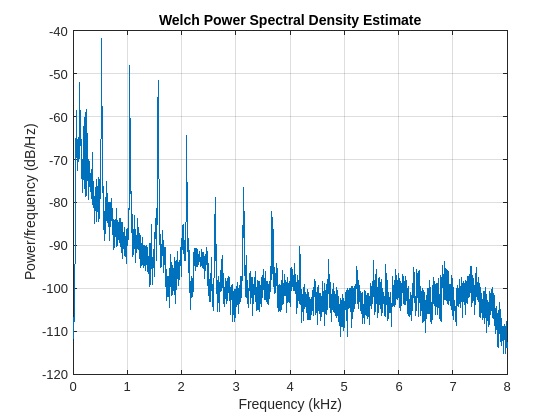

[flute,fs] = audioread("./data/NoisyFlute.wav");
flute = flute(1:3*fs);
t = ((0:numel(flute)-1)/fs)';
yin = chirp(t,2200,t(end),2500);
marked = flute + yin*0.0005;
pwelch(marked,[],[],[],fs)

## Task 1

In this lesson, you'll use the **Design Filter** task to interactively design different filters. To add a task to a live script, go to the **Live Editor** tab, click **Task**, and select from the available tasks.

To find the **Design Filter** task, you can also search for it.

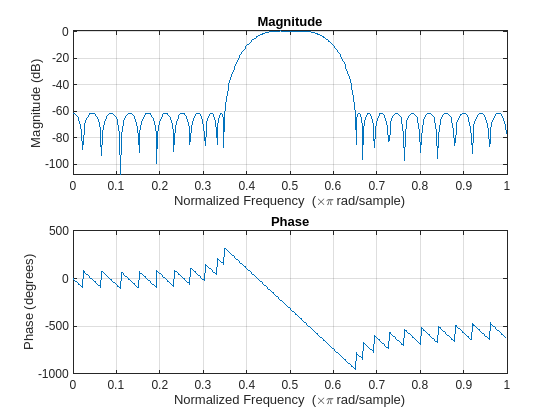

% Design a digital filter
designedFilter = designfilt('bandpassfir', ...
    'StopbandFrequency1',0.35,'PassbandFrequency1',0.45, ...
    'PassbandFrequency2',0.55,'StopbandFrequency2',0.65, ...
    'StopbandAttenuation1',60,'PassbandRipple',1, ...
    'StopbandAttenuation2',60);

% Visualize magnitude and phase responses
freqz(designedFilter.Coefficients)

## Task 2

The output from the **Design Filter** task is `digitalFilter` object where the filter coefficients and specifications are properties of the object. Try entering `designedFilter` as a command in the script to see a summary of the object. You can use `digitalFilter` objects similarly to how you use coefficient vectors `b` and `a`.

For example, to apply the filter, you can use the `filter` function:

`out` `=` `filter``(``df``,``sig``)`

yout = filter(designedFilter,marked);

## Task 3

To see the impact of the filter on the signal, you can either view the time domain or the frequency domain. For now, you can use the `pwelch` function with default inputs to see the power spectrum:

`pwelch``(``sig``,``[]``,``[]``,``[]``,``fs``)` 

This function uses Welch's method. For more information, see the *Improving the Power Spectral Density Estimate*.

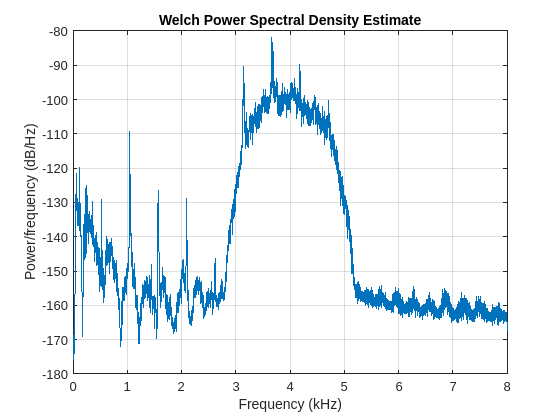

pwelch(yout,[],[],[],fs)